# Trabajo práctico: Filtrado FIR

### Ejercicio 1

freqn_hz = 100; %[hz]
freq_s = 1200;
t_s = 1/freq_s;
t_0 = 0;
t_f = 0.2;
n = t_0:t_s:t_f;
x = sin(2*pi*freqn_hz*n);
target_snr = 15; %[dB]
noisy_x = awgn(x, target_snr,"measured");
freq_co = 2*freqn_hz;
F_co = freq_co/freq_s;
N_max = ceil(1/(2*F_co)); % max window size
N = N_max;
b = (1/N)*ones(1,N);
a = 1;
filtered_x_N_max = filter(b,a,noisy_x);
N_half = ceil(N_max/2);
b_half = (1/N_half)*ones(1,N_half);
filtered_x_half_N_max = filter(b_half,a,noisy_x);
N_ten = 10*N_max;
b_ten = (1/N_ten)*ones(1,N_ten);
filtered_x_ten_N_max = filter(b_ten,a,noisy_x);

Respuesta en frecuencia y fase del filtro MA.

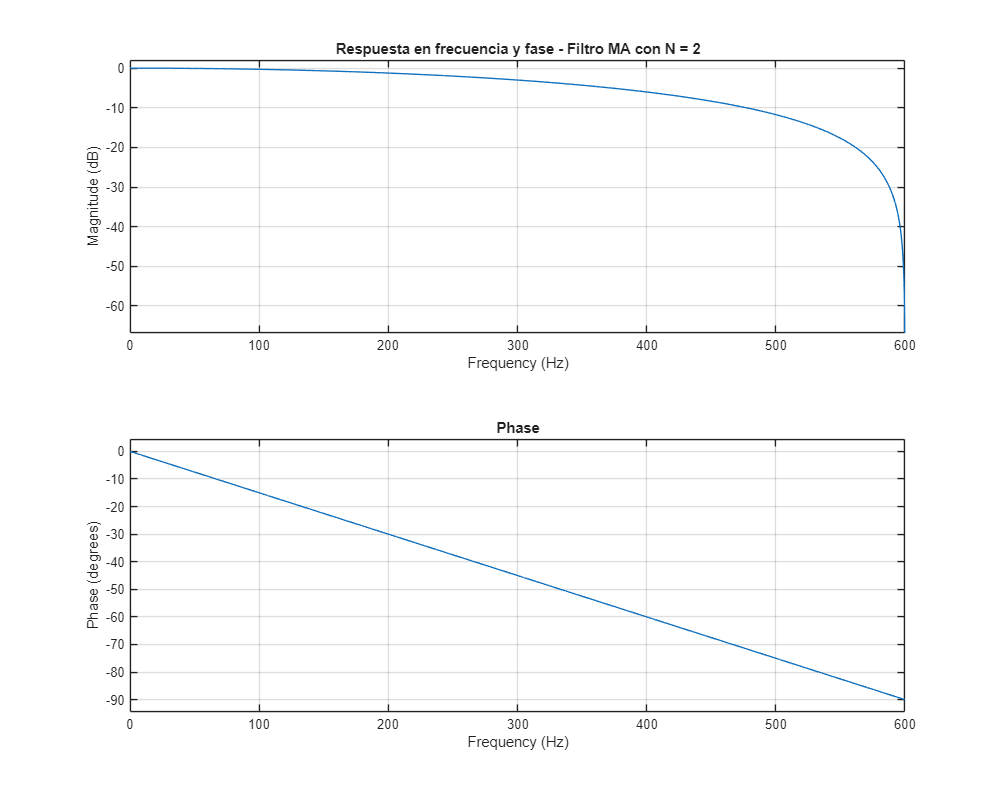

[H_half,f] = freqz(b_half,a,4096,freq_s);
mag_dB_half = 20*log10(abs(H_half));
idx_half = find(mag_dB_half <= -3, 1, 'first');
f_cut_half = f(idx_half);

[H_full,~] = freqz(b,a,4096,freq_s);
mag_dB_full = 20*log10(abs(H_full));
idx_full = find(mag_dB_full <= -3, 1, 'first');
f_cut_full = f(idx_full);

[H_ten,~] = freqz(b_ten,a,4096,freq_s);
mag_dB_ten = 20*log10(abs(H_ten));
idx_ten = find(mag_dB_ten <= -3, 1, 'first');
f_cut_ten = f(idx_ten);

figure('Position',[100 100 1000 800]);
freqz(b_half, a, 4096, freq_s);
title(['Respuesta en frecuencia y fase - Filtro MA con N = ', num2str(N_half)]);

disp(['Frecuencia de corte real para N = N_max/2: ', num2str(f_cut_half), ' Hz']);

Frecuencia de corte real para N = N_max/2: 299.5605 Hz


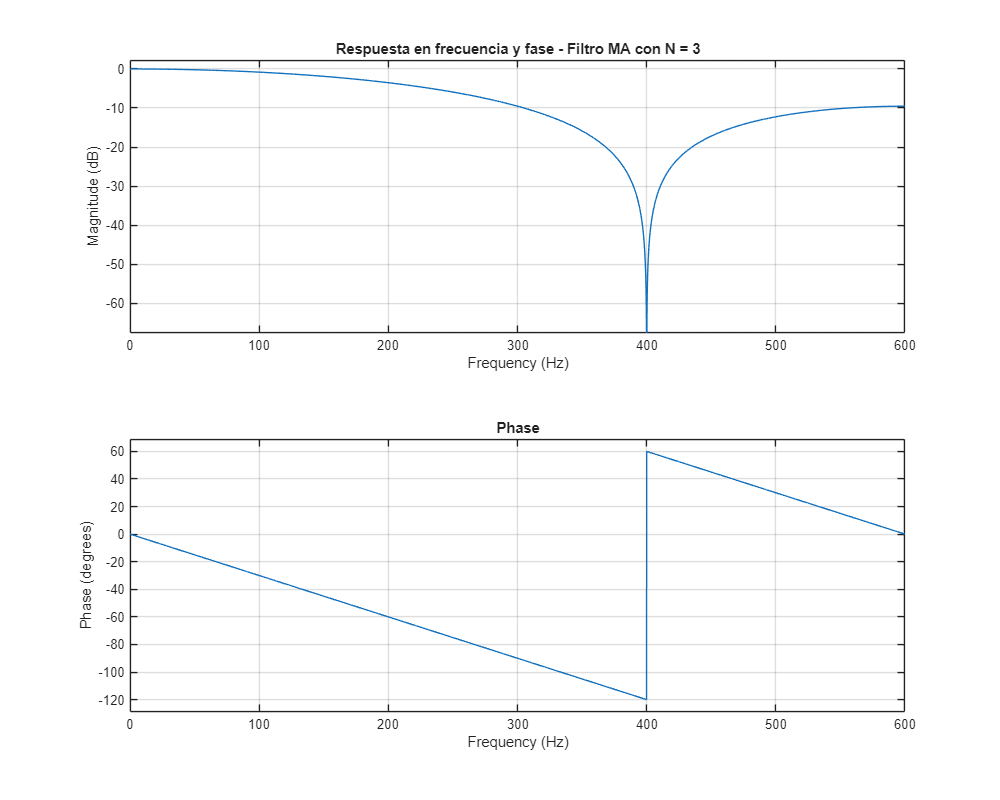

freqz(b, a, 4096, freq_s);
title(['Respuesta en frecuencia y fase - Filtro MA con N = ', num2str(N_max)]);

disp(['Frecuencia de corte real para N = N_max: ', num2str(f_cut_full), ' Hz']);

Frecuencia de corte real para N = N_max: 186.1816 Hz


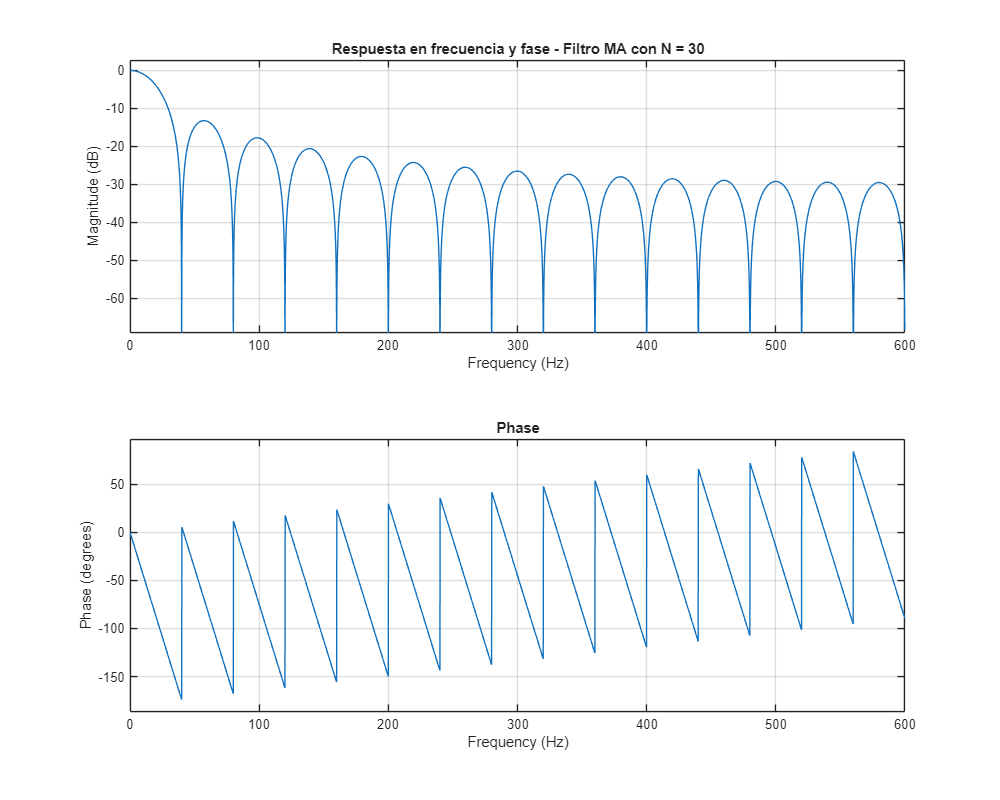

freqz(b_ten, a, 4096, freq_s);
title(['Respuesta en frecuencia y fase - Filtro MA con N = ', num2str(N_ten)]);

disp(['Frecuencia de corte real para N = 10*N_max: ', num2str(f_cut_ten), ' Hz']);

Frecuencia de corte real para N = 10*N_max: 17.7246 Hz


Señales en el dominio del tiempo

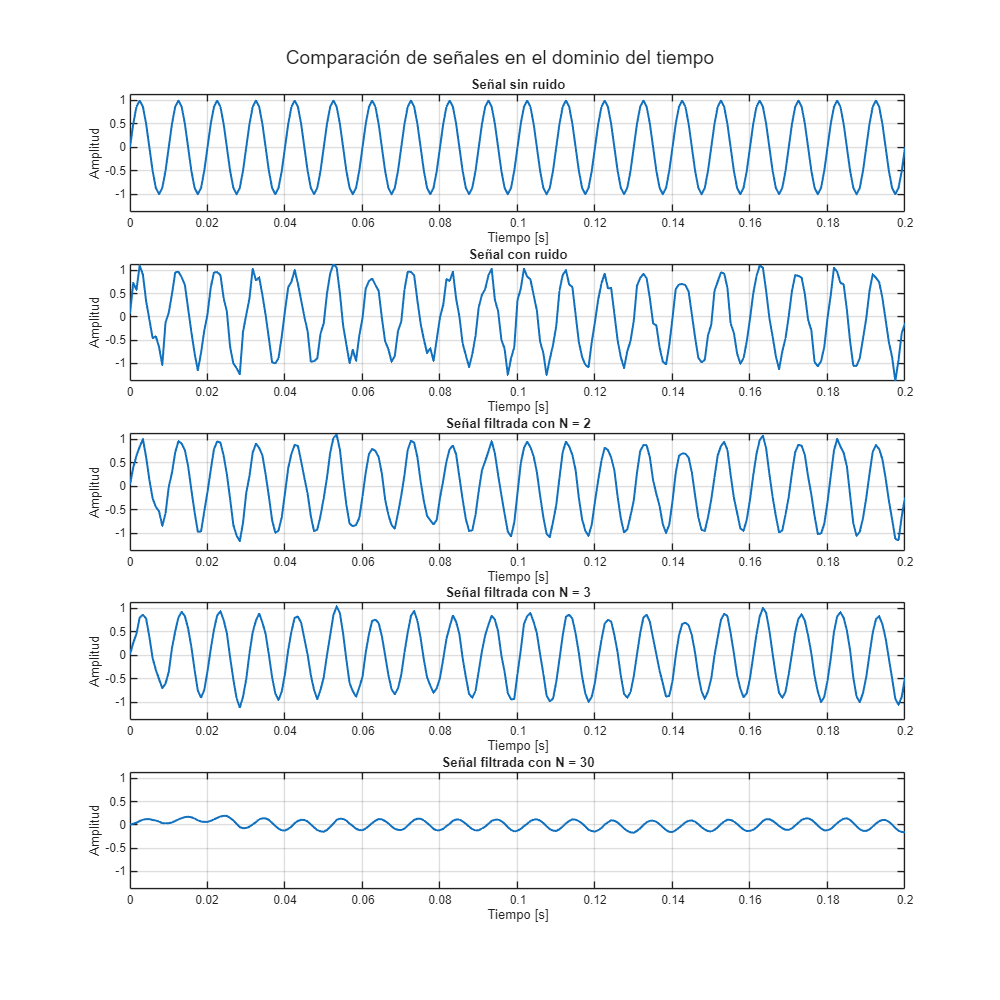

figure('Position',[100 50 1000 1000]);

yl = [min([x noisy_x filtered_x_half_N_max filtered_x_N_max filtered_x_ten_N_max]) ...
      max([x noisy_x filtered_x_half_N_max filtered_x_N_max filtered_x_ten_N_max])];

subplot(5,1,1);
plot(n, x, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal sin ruido');

subplot(5,1,2);
plot(n, noisy_x, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal con ruido');

subplot(5,1,3);
plot(n, filtered_x_half_N_max, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal filtrada con N = ', num2str(ceil(N_max/2))]);

subplot(5,1,4);
plot(n, filtered_x_N_max, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal filtrada con N = ', num2str(N_max)]);

subplot(5,1,5);
plot(n, filtered_x_ten_N_max, 'LineWidth', 1.5);
grid on;
ylim(yl);
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal filtrada con N = ', num2str(10*N_max)]);

sgtitle('Comparación de señales en el dominio del tiempo');

% SNR de entrada
noise_in = noisy_x - x;
snr_in = 10*log10(sum(x.^2)/sum(noise_in.^2));

%% SNR de salida para N = ceil(N_max/2)
N = ceil(N_max/2);
delay = floor((N-1)/2);

x_aligned = x(1:end-delay);
filtered_aligned = filtered_x_half_N_max(delay+1:end);

noise_out = filtered_aligned - x_aligned;
snr_out_half = 10*log10(sum(x_aligned.^2)/sum(noise_out.^2));

%% SNR de salida para N = N_max
N = N_max;
delay = floor((N-1)/2);

x_aligned = x(1:end-delay);
filtered_aligned = filtered_x_N_max(delay+1:end);

noise_out = filtered_aligned - x_aligned;
snr_out_max = 10*log10(sum(x_aligned.^2)/sum(noise_out.^2));

%% SNR de salida para N = 10*N_max
N = 10*N_max;
delay = floor((N-1)/2);

x_aligned = x(1:end-delay);
filtered_aligned = filtered_x_ten_N_max(delay+1:end);

noise_out = filtered_aligned - x_aligned;
snr_out_ten = 10*log10(sum(x_aligned.^2)/sum(noise_out.^2));

%% Mostrar resultados
disp(['SNR de entrada              = ', num2str(snr_in), ' dB']);

SNR de entrada              = 14.484 dB


disp(['SNR de salida N=N_max/2    = ', num2str(snr_out_half), ' dB']);

SNR de salida N=N_max/2    = 10.7505 dB


disp(['SNR de salida N=N_max      = ', num2str(snr_out_max), ' dB']);

SNR de salida N=N_max      = 16.3453 dB


disp(['SNR de salida N=10*N_max   = ', num2str(snr_out_ten), ' dB']);

SNR de salida N=10*N_max   = 1.0933 dB


Para valores grandes de N, el filtro de media móvil introduce una fuerte atenuación en la señal útil, ya que su frecuencia se encuentra dentro de la banda de rechazo del filtro. Como consecuencia, aunque el ruido se reduce, la distorsión de la señal provoca una degradación significativa del SNR.

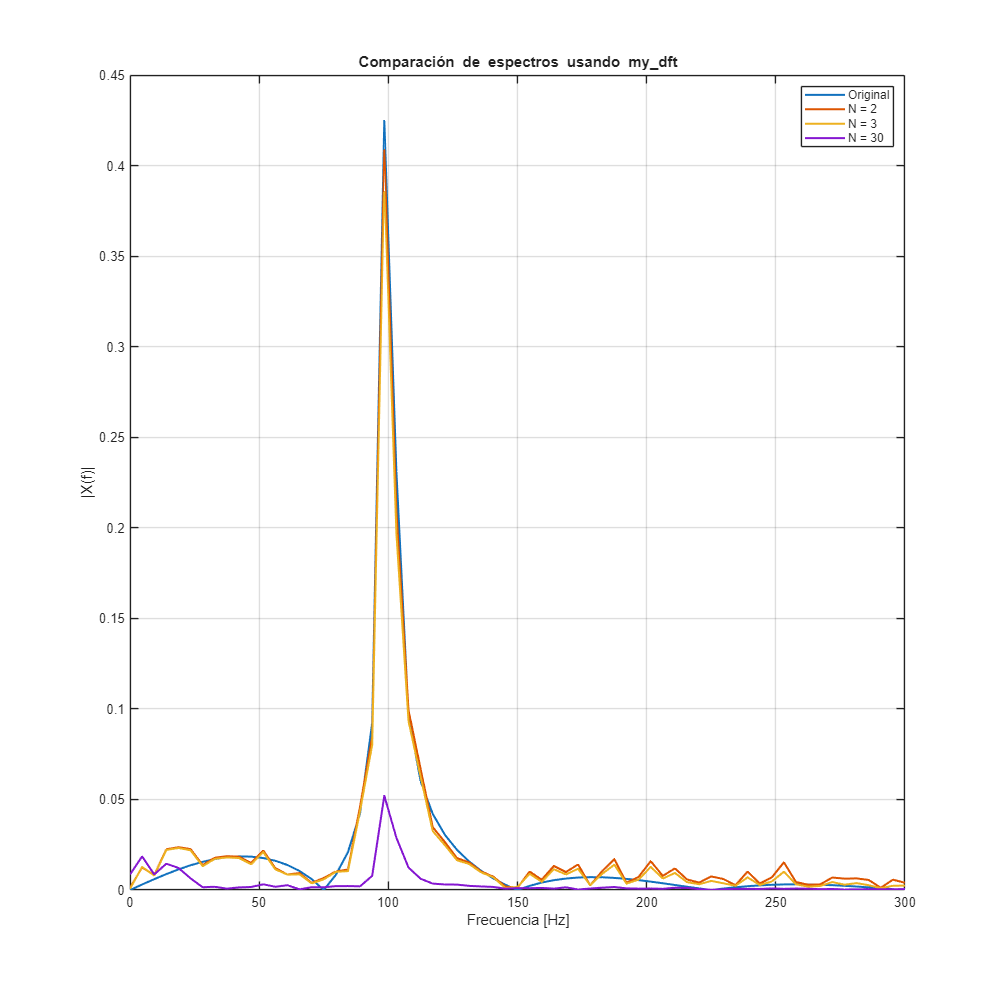

[f_x, mag_x, phase_x, dft_x, NFFT_x] = my_dft(x, freq_s);
[f_half, mag_half, phase_half, dft_half, NFFT_half] = my_dft(filtered_x_half_N_max, freq_s);
[f_full, mag_full, phase_full, dft_full, NFFT_full] = my_dft(filtered_x_N_max, freq_s);
[f_ten, mag_ten, phase_ten, dft_ten, NFFT_ten] = my_dft(filtered_x_ten_N_max, freq_s);

yl = [0 max([mag_x; mag_half; mag_full; mag_ten])];

figure('Position',[100 50 1000 1000]);
plot(f_x, mag_x, 'LineWidth', 1.5); hold on;
plot(f_half, mag_half, 'LineWidth', 1.5);
plot(f_full, mag_full, 'LineWidth', 1.5);
plot(f_ten, mag_ten, 'LineWidth', 1.5);
grid on;
xlim([0 freq_s/4]);
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|');
title('Comparación de espectros usando my\_dft');
legend('Original', ['N = ', num2str(N_half)], ['N = ', num2str(N_max)], ['N = ', num2str(N_ten)]);

En el grafico de respuesta en frecuencia puede verse claramente lo que se dijo previamente, la gran atenuación de la frecuencia de relevancia (100 Hz) hace que se pierda por completo la señal original, aunque, atenúe mejor las altas frecuencias.

### Ejercicio 2

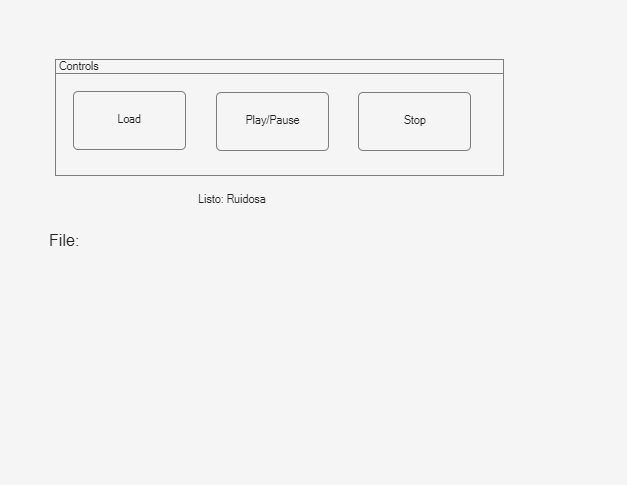

channel_1 = signal(:,1);
target_snr = 50; % [dB]
noisy_ch1 = awgn(channel_1, target_snr, 'measured');
freq_co = 22050; %freq corte [hz]
norm_freq_co = freq_co/Fs;
N_max = 1/(2*norm_freq_co);
N = N_max;
b = 1/(N)*ones(1,N_max);
filt_ch1 = filter(b,1,noisy_ch1);
pruebasonido(noisy_ch1, Fs, "Ruidosa");

pruebasonido(channel_1, Fs, "Original");
pruebasonido(filt_ch1, Fs, "Filtrada MA");


Audioplayer GUI (modificada para multi-instancia):

Juan Pinzon (2026). Simple Audio Player GUI (https://la.mathworks.com/matlabcentral/fileexchange/53443-simple-audio-player-gui), MATLAB Central File Exchange. Recuperado 13 abril, 2026. 

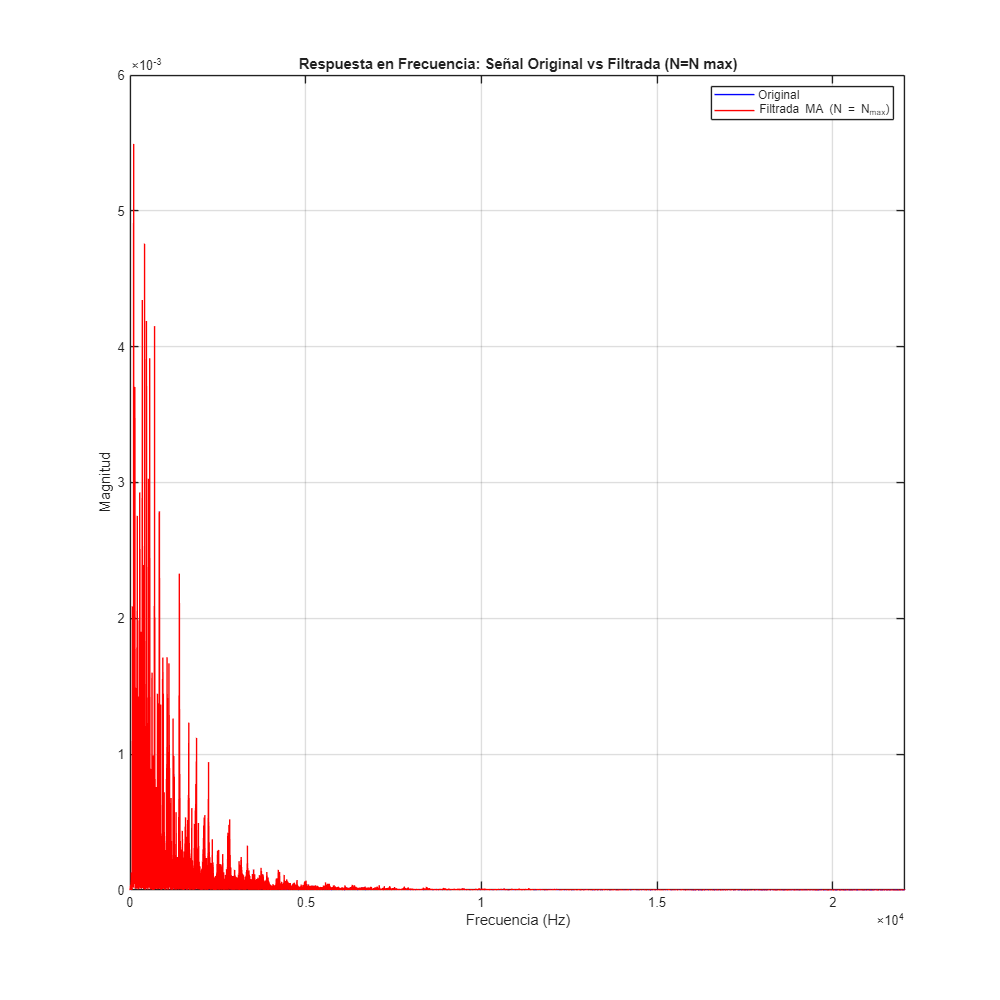

[f_orig, mag_orig, ~, ~, ~] = my_dft(channel_1, Fs);
[f_filt, mag_filt, ~, ~, ~] = my_dft(filt_ch1, Fs);
figure('Name', 'Consigna F - Comparación en Frecuencia','Position',[100 50 1000 1000]);
plot(f_orig, mag_orig, 'b', 'DisplayName', 'Original');
hold on;
plot(f_filt, mag_filt, 'r', 'DisplayName', 'Filtrada MA (N = N_{max})');
title('Respuesta en Frecuencia: Señal Original vs Filtrada (N=N max)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
legend;
grid on;

xlim([0 Fs/2]);

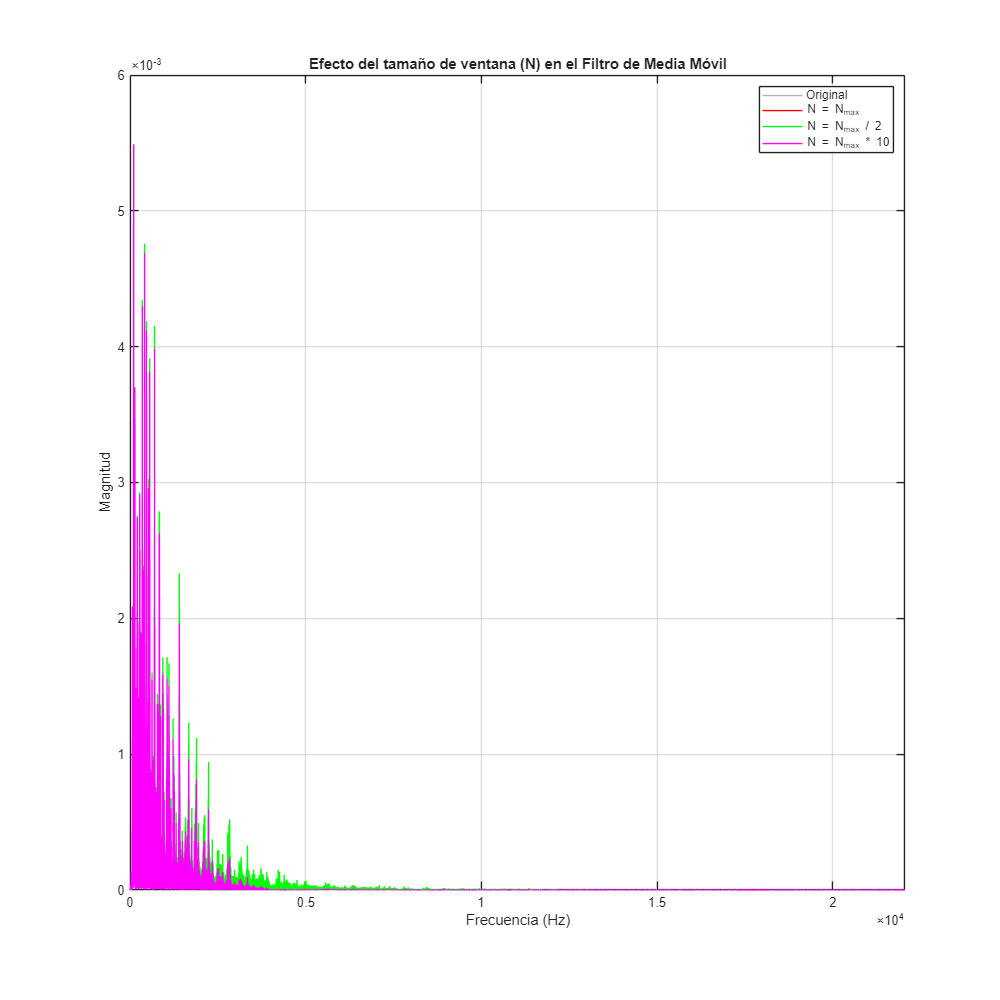

N_half = round(N_max / 2); % Usamos round() para asegurar un número entero
b_half = (1 / N_half) * ones(1, N_half);
filt_ch1_half = filter(b_half, 1, noisy_ch1);
%--- 
N_10 = round(N_max * 10);
b_10 = (1 / N_10) * ones(1, N_10);
filt_ch1_10 = filter(b_10, 1, noisy_ch1);
%---
[f_half, mag_half, ~, ~, ~] = my_dft(filt_ch1_half, Fs);
[f_10, mag_10, ~, ~, ~] = my_dft(filt_ch1_10, Fs);
figure('Name', 'Comparación de N','Position',[100 50 1000 1000]);
plot(f_orig, mag_orig, 'Color', [0.7 0.7 0.7], 'DisplayName', 'Original'); % Gris para que no sature
hold on;
plot(f_filt, mag_filt, 'r', 'DisplayName', 'N = N_{max}');
plot(f_half, mag_half, 'g', 'DisplayName', 'N = N_{max} / 2');
plot(f_10, mag_10, 'm', 'DisplayName', 'N = N_{max} * 10');
title('Efecto del tamaño de ventana (N) en el Filtro de Media Móvil');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
legend;
grid on;
xlim([0 Fs/2]);

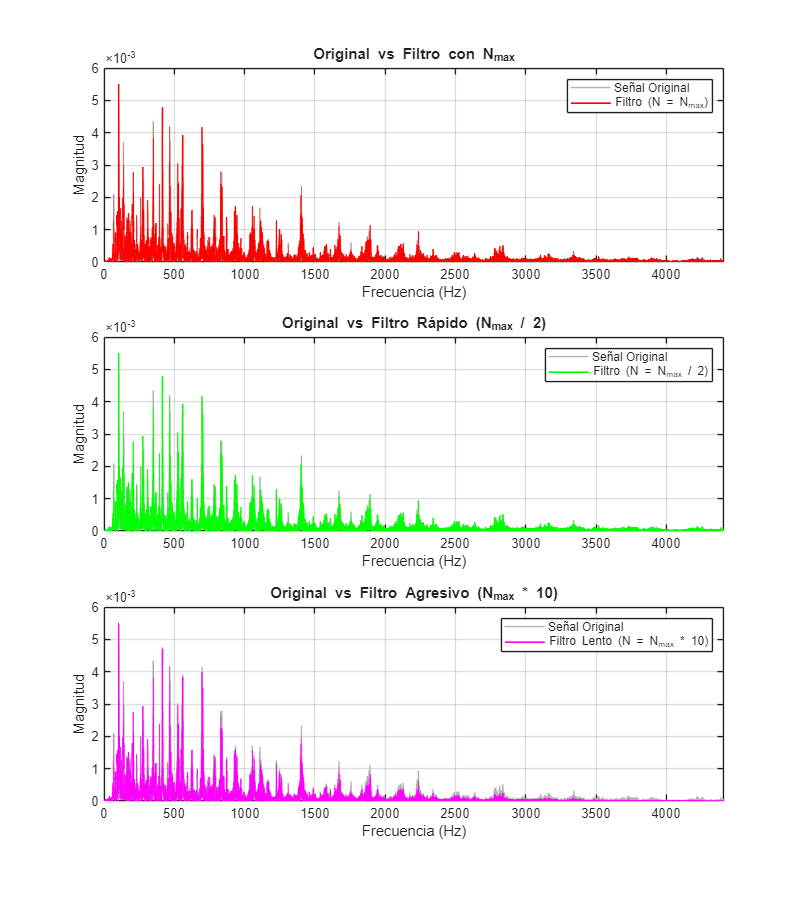

% Creamos una figura más alta para que los 3 gráficos entren bien
figure('Name', 'Comparación Individual de Filtros', 'Position', [100, 100, 800, 900]);

% --- Gráfico 1: Original vs N = N_max ---
subplot(3, 1, 1); % (3 filas, 1 columna, posición 1)
plot(f_orig, mag_orig, 'Color', [0.7 0.7 0.7], 'DisplayName', 'Señal Original'); 
hold on;
plot(f_filt, mag_filt, 'r', 'LineWidth', 1.2, 'DisplayName', 'Filtro (N = N_{max})');
title('Original vs Filtro con N_{max}');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
legend;
grid on;
xlim([0 Fs/10]);

% --- Gráfico 2: Original vs N = N_max / 2 ---
subplot(3, 1, 2); % (3 filas, 1 columna, posición 2)
plot(f_orig, mag_orig, 'Color', [0.7 0.7 0.7], 'DisplayName', 'Señal Original'); 
hold on;
plot(f_half, mag_half, 'g', 'LineWidth', 1.2, 'DisplayName', 'Filtro (N = N_{max} / 2)');
title('Original vs Filtro Rápido (N_{max} / 2)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
legend;
grid on;
xlim([0 Fs/10]);

% --- Gráfico 3: Original vs N = N_max * 10 ---
subplot(3, 1, 3); % (3 filas, 1 columna, posición 3)
plot(f_orig, mag_orig, 'Color', [0.7 0.7 0.7], 'DisplayName', 'Señal Original'); 
hold on;
plot(f_10, mag_10, 'm', 'LineWidth', 1.2, 'DisplayName', 'Filtro Lento (N = N_{max} * 10)');
title('Original vs Filtro Agresivo (N_{max} * 10)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
legend;
grid on;
xlim([0 Fs/10]);

### Ejercicio 3

(*Necesario correr la primer section del archivo*

fs_array = [1200, 2000, 5000, 10000];

% Preasignamos un arreglo para guardar los resultados del RMSE
errores = zeros(length(fs_array), 1);
ordenes_N = zeros(length(fs_array), 1);
% Bucle para evaluar cada frecuencia de muestreo
for i = 1:length(fs_array)
    freq_s = fs_array(i);
    
    % 1. Generar vector de tiempo y señales
    t_s = 1/freq_s;
    n = t_0:t_s:t_f;
    
    x = sin(2*pi*freqn_hz*n); % Señal limpia (ideal / de referencia)
    noisy_x = awgn(x, target_snr, "measured"); % Señal de entrada con ruido
    
    % 2. Calcular el nuevo orden N manteniendo fco constante
    F_co = freq_co / freq_s;
    N = ceil(1 / (2*F_co));
    ordenes_N(i) = N;
    retraso = round((N-1)/2);
    % 3. Construir y aplicar el filtro MA
    b = (1/N) * ones(1,N);
    a = 1;
    filtered_x = filter(b, a, noisy_x); % Señal de salida
    senal_filtrada_alineada = filtered_x(retraso+1:end);
    senal_original_alineada = x(1:end-retraso);
    error_actual = rmse(x, filtered_x);
    error_real = rmse(senal_original_alineada, senal_filtrada_alineada);
    errores(i) = error_real;
    
    fprintf('fs = %5d Hz | Orden N = %2d | RMSE = %.4f\n', freq_s, N, error_real);
end

fs =  1200 Hz | Orden N =  3 | RMSE = 0.0921
fs =  2000 Hz | Orden N =  5 | RMSE = 0.0806
fs =  5000 Hz | Orden N = 13 | RMSE = 0.0764
fs = 10000 Hz | Orden N = 25 | RMSE = 0.0698


Resultados del Filtro MA con Oversampling

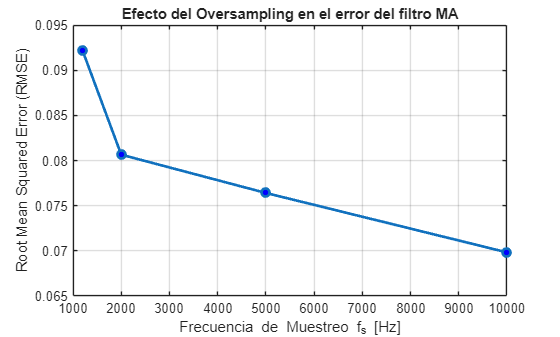

% Visualización rápida para entender el efecto
figure;
plot(fs_array, errores, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
xlabel('Frecuencia de Muestreo f_s [Hz]');
ylabel('Root Mean Squared Error (RMSE)');
title('Efecto del Oversampling en el error del filtro MA');
grid on;

## Ejercicio 4

Ventana Kaiser, Orden 10:

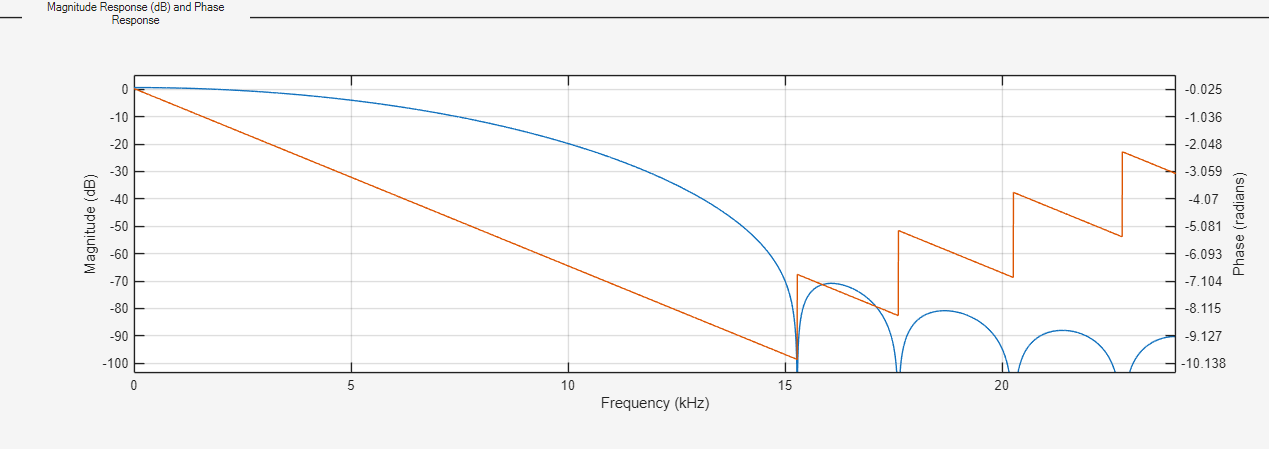

Ventana Kaiser, Orden 100:

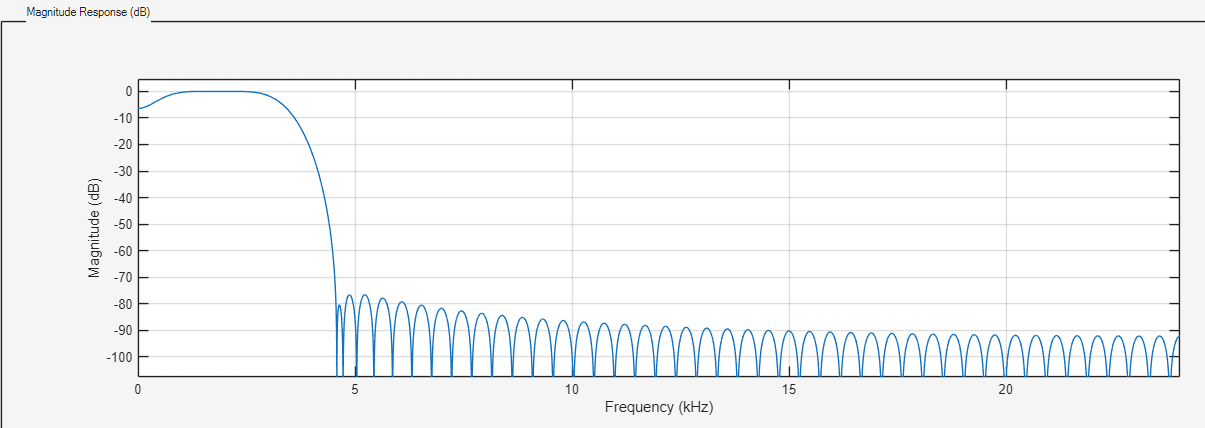

Si, se modifica sustancialmente la respuesta en frecuencia, siendo siendo mas pronunciada la atenuacion

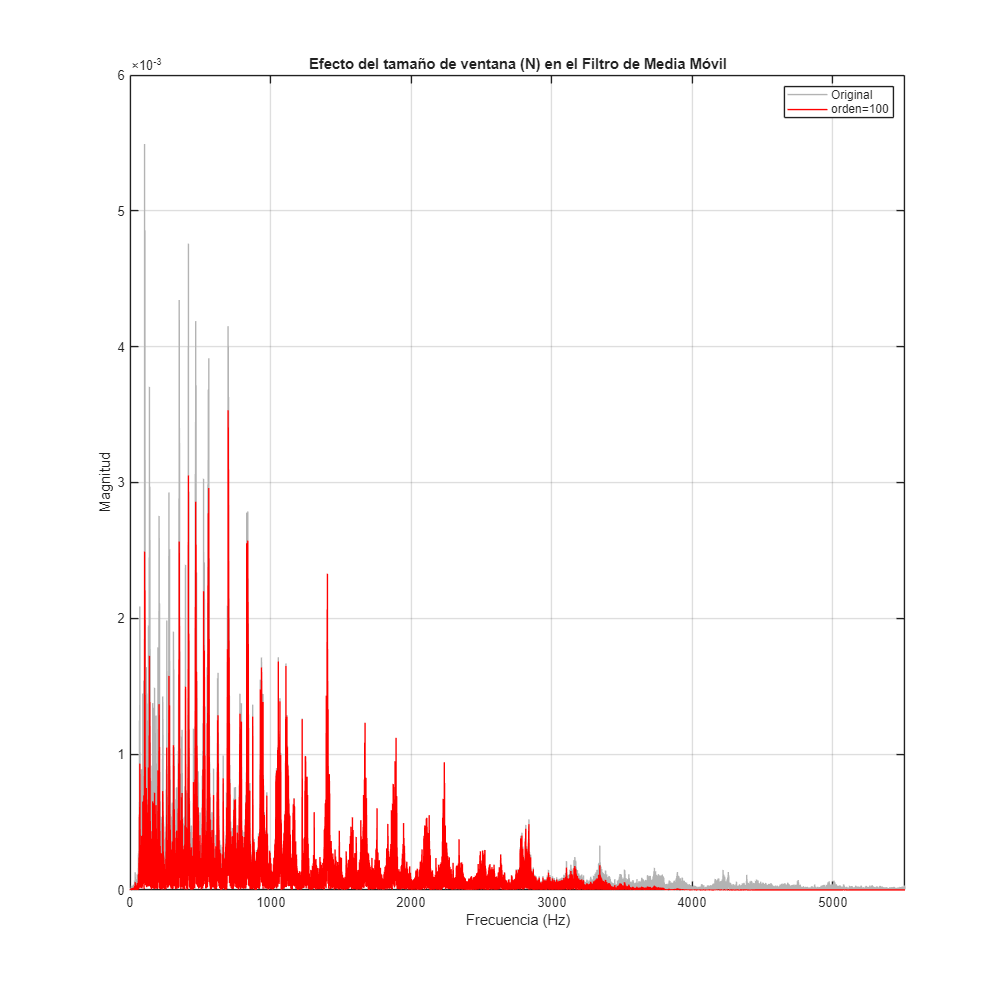

kaiser100 = kaiser100th();
load("Tchaikovsky.mat")
ch1 = signal(:,1);
filt_ch1 = filter(kaiser100, ch1);
[f_kaiser, mag_kaiser, ~, ~, ~] = my_dft(filt_ch1, Fs);
[f_orig, mag_orig, ~, ~, ~] = my_dft(ch1, Fs);

figure('Name', 'Comparación de N','Position',[100 50 1000 1000]);
plot(f_orig, mag_orig, 'Color', [0.7 0.7 0.7], 'DisplayName', 'Original'); % Gris para que no sature
hold on;
plot(f_kaiser, mag_kaiser, 'r', 'DisplayName', 'orden=100');
title('Efecto del tamaño de ventana (N) en el Filtro de Media Móvil');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
legend;
grid on;
xlim([0 Fs/8]);

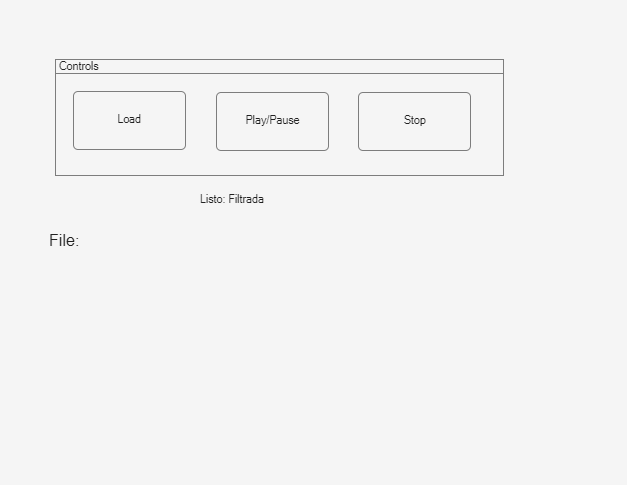

pruebasonido(filt_ch1,Fs,"Filtrada");

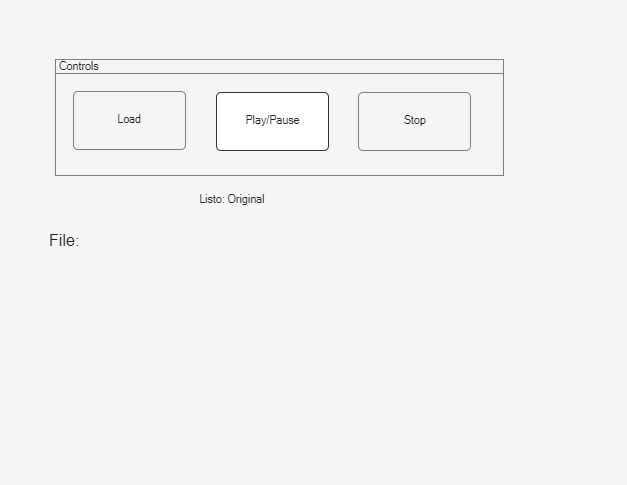

pruebasonido(ch1,Fs,"Original");

.

### Ejercicio 5

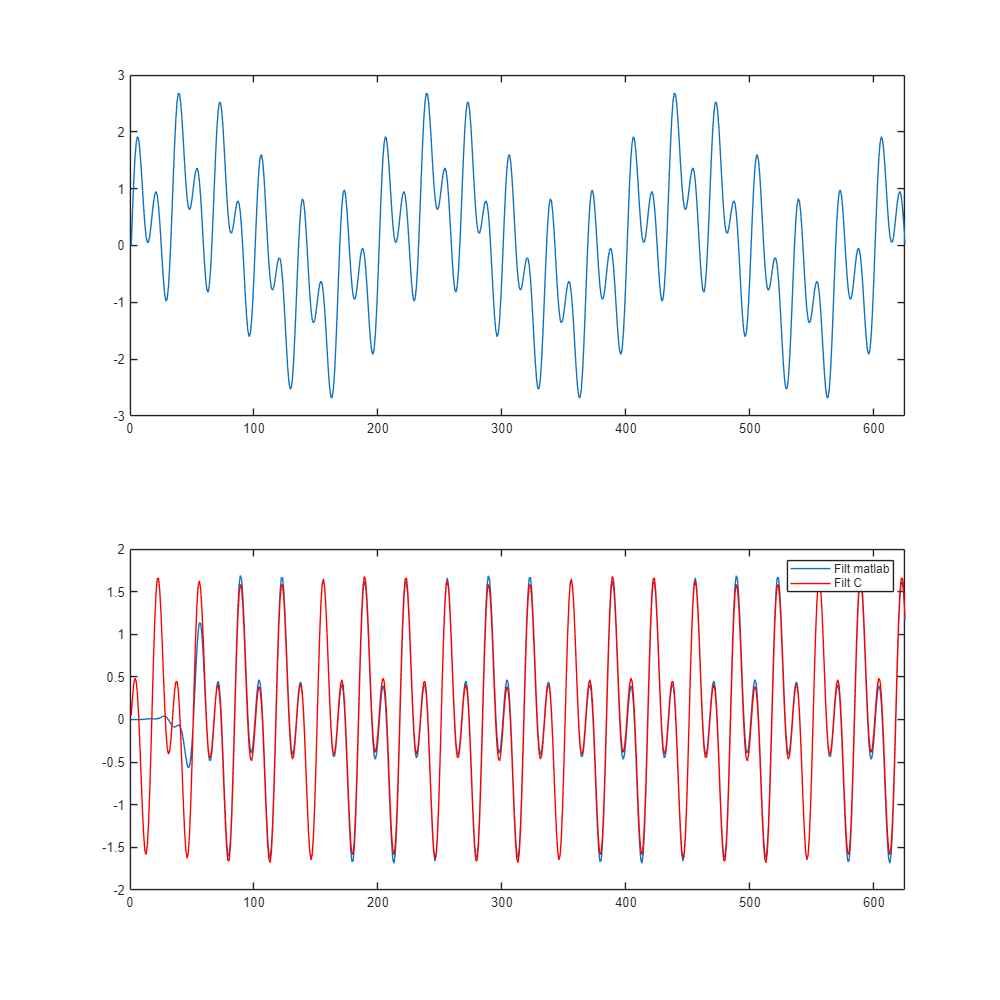

Fs = 10e3;
dt = 1/Fs;
t=0:dt:0.5;
raw_signal = sin(2*pi*300*t)+sin(2*pi*600*t);
noisy_signal = raw_signal + sin(2*pi*50*t);
filtro = kaiser200_800();
filt_signal_matlab = filter(filtro,noisy_signal);
N=length(t);
filt_signal_c = fir_wrapper(single(noisy_signal'));
figure('Name',"raw",'Position',[100 50 1000 1000]);
subplot(2,1,1);
plot(noisy_signal,'DisplayName',"Original");
xlim([0 N/8]);
subplot(2,1,2);
plot(filt_signal_matlab,'DisplayName',"Filt matlab");
hold on;
xlim([0 N/8]);
legend;
plot(filt_signal_c, 'r','DisplayName','Filt C');
xlim([0 N/8]);

La diferencia entre uno y otro es por la naturaleza de los filtros, ambos pretenden lo mismo, pero uno esta aplicado de forma causal, mientras que el otro esta aplicado de forma anticausal, ya que es el filtro offline.